# How pixel size influences the modulation transfer function (MTF)

This is just the last part of the fclSensorFundamentals live script.  I am planning to expand it in the future to consider different aspects of the MTF. For now please ignore it.

The basic approach to calculating the MTF is shown in the latter part of the fclSensorFundamentals live script.  These are the steps

- Define a slanted edge scene

- Create an optical image from the scene

- Define a sensor

- Evaluate the sensor MTF over a range of possible sensor parameters (pixel size) 

- We measure the system MTF properties using a simple slanted bar target along with the **ISO 12233** standard methods.

This script is going to spend some time unpacking the ISO 12233 method, showing some of its steps in more detail.  Also, we will consider the impact of noise (e.g., photon noise at different mean levels) on the MTF.

**See also:  **fclSensorFundamentals.mlx

## Initialize parameters

The parameter list defines some optical properties (f/# of a diffraction limited lens), and some sensor properties (how big is the dye and how big is the pixel size).  This emphasizes the interaction between the different system components!

ieInit;

% List of parameters we will set
fNumber = 4;
dyeSizeMicrons = 512;            % Microns

clear psSize;
pSize = [1 2 4 8];                % Microns

## Create a test image: the slanted bar image

scene = sceneCreate('slantedBar',512);

% Now we will set the parameters of these various objects.
% First, let's set the scene field of view.
scene = sceneAdjustLuminance(scene,100);    % Candelas/m2
scene = sceneSet(scene,'distance',1);       % meters
scene = sceneSet(scene,'fov',5);            % Field of view in degrees
% sceneWindow(scene);

## Create an optical image with some default optics.

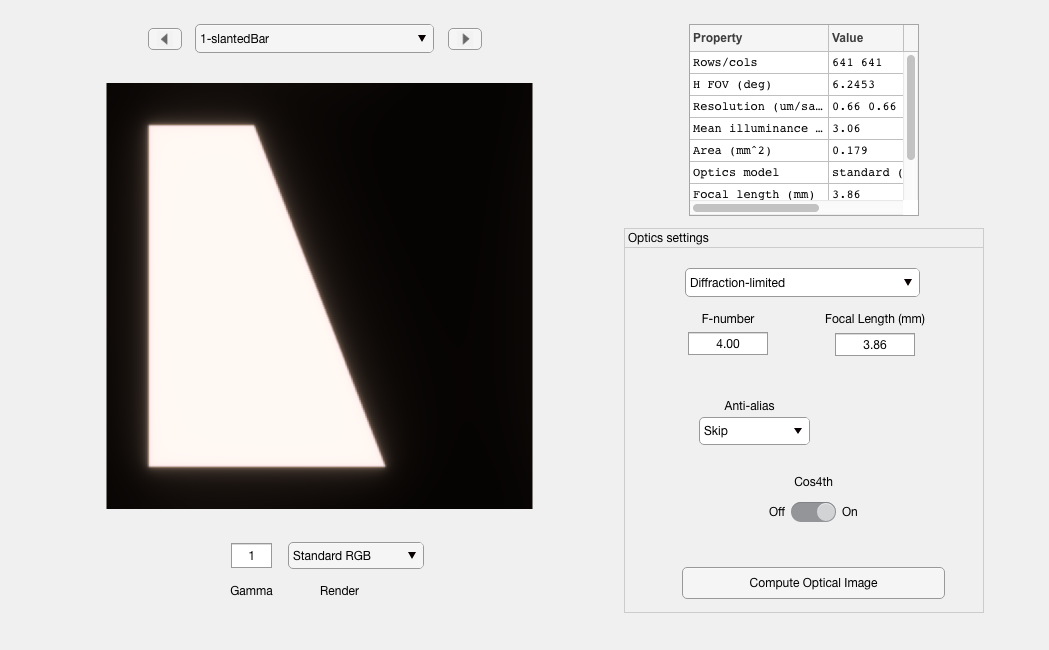

oi = oiCreate;
oi = oiSet(oi,'optics fnumber',fNumber);

% Now, compute the optical image from this scene and the current optical
% image properties
oi = oiCompute(oi,scene);

oiWindow(oi);

## Create a default monochrome image sensor array

We are  ready to set pixel sizes to produce a variety of captured images.  We will do the calculation for a monochrome sensor, but you might try experiments with a color sensor.

% Initialize
sensor = sensorCreate('monochrome');

% Make sure we get enough light
sensor = sensorSet(sensor,'autoExposure',1);

% The calculation will include the impact of the 
% image processing routines!
ip = ipCreate;


## Compute MTF for different pixel sizes

Black border detected


Black border detected


Black border detected


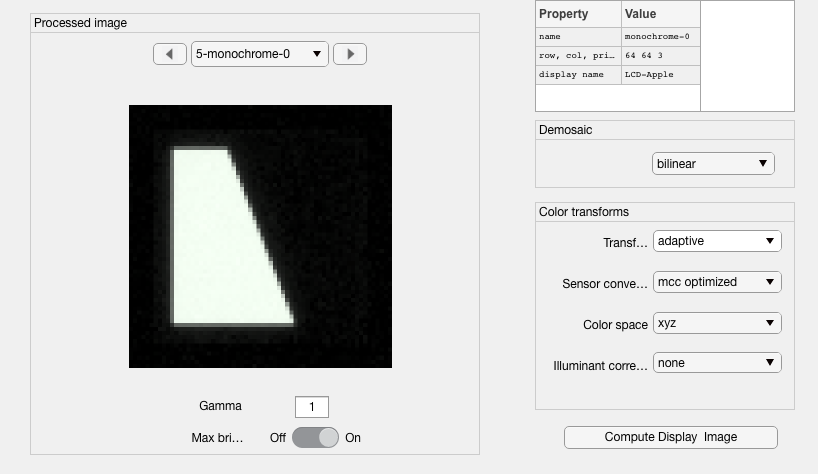

Black border detected


mtfData = cell(1,length(pSize));
for ii=1:length(pSize)
    
    % Adjust the pixel size (meters)
    sensor = sensorSet(sensor,'pixel size constant fill factor',[pSize(ii) pSize(ii)]*1e-6);

    % Adjust the sensor row and column size so that 
    % the sensor has a constant field of view.
    sensor = sensorSet(sensor,'rows',round(dyeSizeMicrons/pSize(ii)));
    sensor = sensorSet(sensor,'cols',round(dyeSizeMicrons/pSize(ii)));

    sensor = sensorCompute(sensor,oi);
    ieReplaceObject(sensor); 
    % sensorWindow(sensor);
     
    ip = ipCompute(ip,sensor);
    ieReplaceObject(ip);
    
    % After the calculation, look at the ISET-IP window 
    % at the different images. 
    % You will see the varying spatial resolution. 
    ipWindow(ip);
    
    % This routine applies the ISO standard to calculate the MTF
    mtfData{ii} = ieISO12233(ip,sensor,'none');
end


## Summary plot

The cell array *mtfData*  contains all the information plotted in this figure.  We graph the results and compare the MTFs for different pixel sizes.

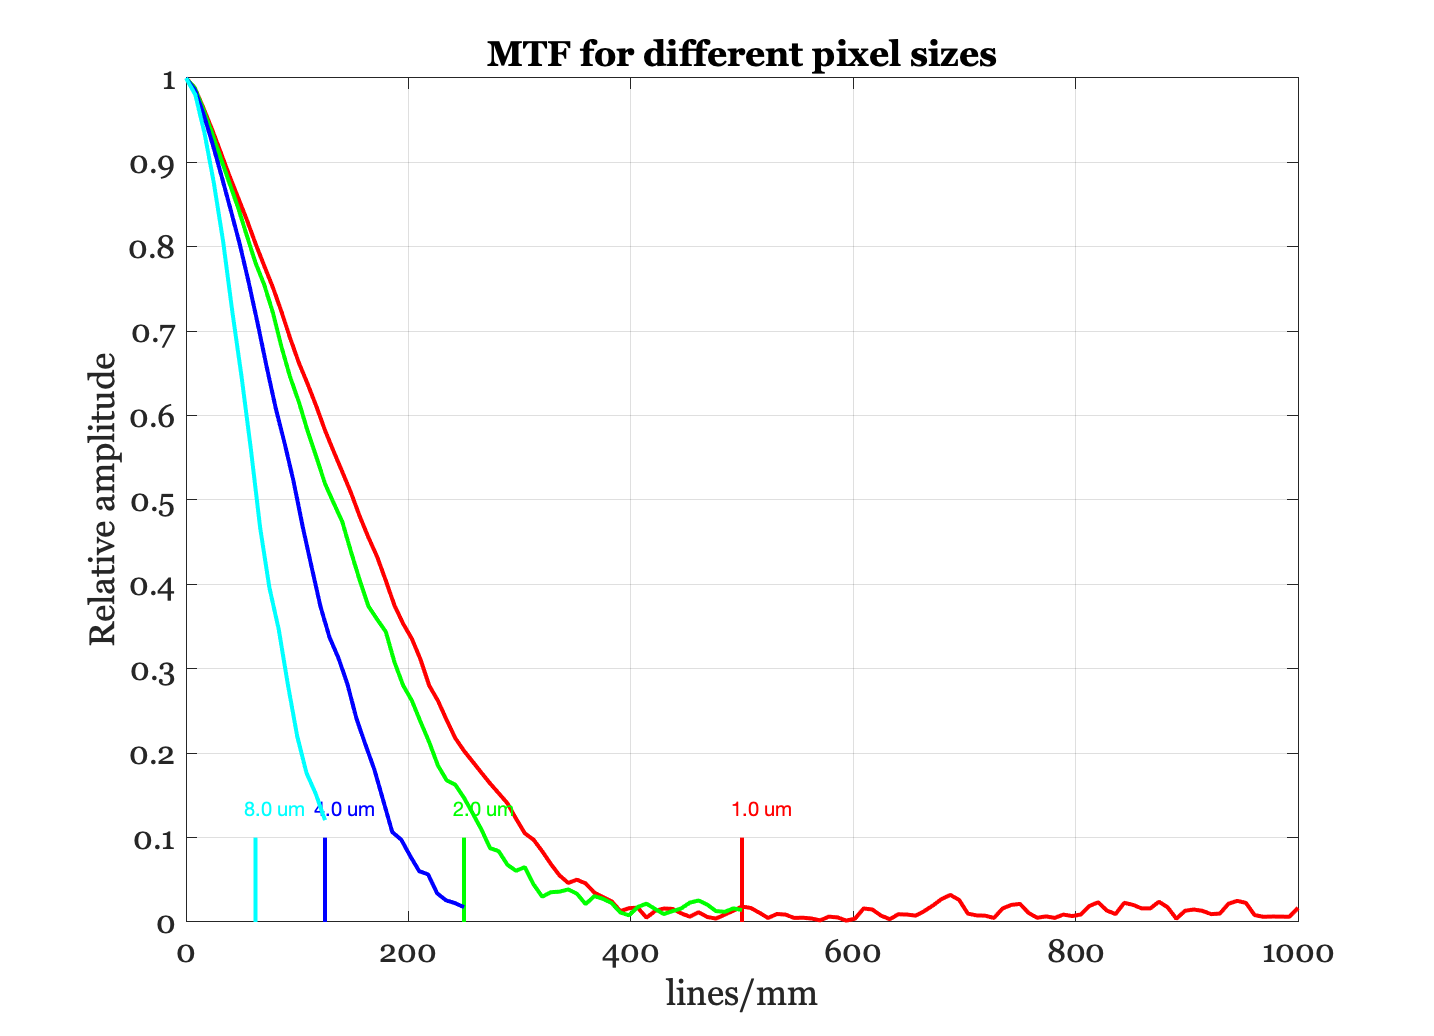

ieNewGraphWin;
c = {'r','g','b','c','m','y','k'};
for ii=1:length(mtfData)
    h = plot(mtfData{ii}.freq,mtfData{ii}.mtf,['-',c{ii}], ...
        'LineWidth',2);
    hold on
    newText = sprintf('%.1f um\n',pSize(ii));
    nfreq = mtfData{ii}.nyquistf;
    l = line([nfreq ,nfreq],[0.1,0],'color',c{ii});
    l.LineWidth = 2;
    text((nfreq-10),0.12,newText,'color',c{ii});
end

xlabel('lines/mm');
ylabel('Relative amplitude');
title('MTF for different pixel sizes');
hold off; grid on

## **The effects of photon noise on the MTF**

Examine the variation we find in the MTF when we have low or high mean scene luminance

Similarly, what is the impact of exposure duration which effectively 'darkens' the scene